# **Experimental Modal Analysis(EMA):**    2-dof Mechanical System

In the following script we'll analyze a 2-dof Mechanical system.  Specifically we'll 

- Review the Transfer Function matrix for the system

- Review the State Space ODE representation of the system

- Solve the Eigenvalue problem - i.e.:  what are the natural frequencies of vibration

- Simulate the model

- Compute the Transfer Functions from the simulated data

- Look at 3 techniques for **extracting MODAL properties** from a simulated measurement data set

- [`modalfit()`](matlab:  doc  modalfit) `- `we've already looked at this in previous tasks

- [`ssest()`](matlab: doc ssest)        - one of the MANY functions from the [**System Identification toolbox**](https://www.mathworks.com/help/releases/R2025b/ident/index.html)

- [`tf_est()`](matlab: doc tfest)    - one of the MANY functions from the [**System Identification toolbox**](https://www.mathworks.com/help/releases/R2025b/ident/index.html)

## RESOURCES:

The following Appendix files are useful for some background knowledge on topics related to EMA:

- [`APPENDIX_00_Matrix_Algebra_Essentials_for_Modal.mlx`](matlab:  open bh_Modal.APPENDIX_00_Matrix_Algebra_Essentials_for_Modal)  

- [`APPENDIX_01_Modal_Model_Representation.mlx`](matlab:  open  bh_Modal.APPENDIX_01_Modal_Model_Representation)

- [`APPENDIX_02_Complex_Residue_Curve_Fit.mlx`](matlab:  open  bh_Modal.APPENDIX_02_Complex_Residue_Curve_Fit)    

- [`APPENDIX_03_Signal_things.mlx `](matlab:  open  bh_Modal.APPENDIX_03_Signal_things)           

- [`APPENDIX_04_tf_and_frf.mlx`](matlab:  open bh_Modal.APPENDIX_04_tf_and_frf)

- [`APPENDIX_05_irf_and_fft_and_frf.mlx`](matlab:  open bh_Modal.APPENDIX_05_irf_and_fft_and_frf)

- [`APPENDIX_06_PHASE_PLOTS.mlx`](matlab:  open bh_Modal.APPENDIX_06_PHASE_PLOTS)

- [`APPENDIX_07_NATURAL_DAMPED_and_RESONANT.mlx`](matlab:  open bh_Modal.APPENDIX_07_NATURAL_DAMPED_and_RESONANT)

- [`APPENDIX_08_explore_pulse.mlx`](matlab:  open bh_Modal.APPENDIX_08_explore_pulse)

 `Bradley Horton: bhorton@mathworks.com`

## Mechanical:    a 2-dof system

Consider the following undamped 2-dof system:

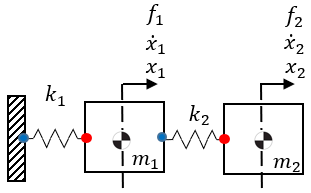

The **Undamped Mechanical equations of motion** for this system are:

- $\pmatrix{
m_1 & 0 \cr
0 & m_2 \cr
}$$. \pmatrix{
\ddot{x}_1 \cr
\ddot{x}_2 \cr
}$  +  $\pmatrix{
(k_1 + k_2) & -k_2 \cr
-k_2 & k_2 \cr
}$$. \pmatrix{
{x}_1 \cr
{x}_2 \cr
}$= $\pmatrix{
{f}_1 \cr
{f}_2 \cr
}$

Which we can write in matrix form as:   

- $M \ddot{x}  +   Kx = f$   where   $x \in R^{P\times1}$    and   $f \in R^{P\times1}$

And let's assume that we have a Proportionately damped matrix C defined as:

- 
$$C=\gamma \ldotp M\;\;+\;\;\beta \ldotp K$$


So the damped **Mechanical equations of motion** for this system is

- 
$$M \ddot{x}  +   C \dot{x}  +  Kx = f$$
   

## Mechanical Transfer Function representation:

For a more detailed discussion on the "Modal Model Representation", see:

- [`APPENDIX_01_Modal_Model_Representation.mlx`](matlab:  open  bh_Modal.APPENDIX_01_Modal_Model_Representation)

Let:

- 
$$L\left\lbrack \;x\left(t\right)\;\right\rbrack =X\left(s\right)\;\;=\;\;\left\lbrack \begin{array}{c}
X_1 \left(s\right)\\
X_2 \left(s\right)
\end{array}\right\rbrack$$


- 
$$L\left\lbrack \;f\left(t\right)\;\right\rbrack =F\left(s\right)\;=\;\;\left\lbrack \begin{array}{c}
F_1 \left(s\right)\\
F_2 \left(s\right)
\end{array}\right\rbrack$$


Taking the **Laplace transform** of the **Damped** **Mechanical equations of motion**, we get (assuming ZERO ICs):

- 
$$\left(M\ldotp s^2 \;\;+\;C\ldotp s\;+\;K\right)\ldotp X\left(s\right)\;=\;\;F\left(s\right)$$


Where our **Transfer Function** matrix is $\left\lbrack H\left(s\right)\right\rbrack$

- 
$$X\left(s\right)\;\;=\;\left\lbrack H\left(s\right)\right\rbrack \ldotp F\left(s\right)$$


The UNDAMPED eigenvalue problem can be solved 

- $\Phi \;\;\;=\;\;\;\left\lbrack \begin{array}{ccccc}
\vec{\phi_1 }  & \vec{\phi_2 }  & \vec{\phi_3 }  & \cdots  & \vec{\phi_P } 
\end{array}\right\rbrack$     where   $\vec{\phi_i } \;\in R^{P\times 1}$   

 and the UNDAMPED modes can be normalized such that:

-         
$$I\;\;\;\;\;=\;\;\Phi^T \ldotp M\ldotp \Phi$$
        

- ${\left\lbrack \omega_n^2 \;\;\;\right\rbrack }_{\mathrm{diag}} =\;\;\Phi^T \ldotp K\ldotp \Phi$      where   $\omega_{\mathbf{ni}}$ is the $i^{\mathrm{th}}$ ***undamped Natural frequency***

Now, Under the assumptions of Proportional damping:

- 
$$C=\gamma \ldotp M\;\;+\;\;\beta \ldotp K\;\;\;\;\;\;\Longrightarrow \;\;\;\;\;\;\;{\left\lbrack 2\ldotp \zeta \ldotp \omega_n \right\rbrack }_{\mathrm{diag}} =\;\;\Phi^T \ldotp C\ldotp \Phi$$
     

Our **Transfer Function matrix** can be written as (see [`HERE`](matlab:  open  bh_Modal.APPENDIX_01_Modal_Model_Representation)):

- 
$$X\left(s\right)\;\;=\;\left\lbrack H\left(s\right)\right\rbrack \ldotp F\left(s\right)$$


- 
$$\left\lbrack H\left(s\right)\right\rbrack \;\;=\;\sum_{i=1}^P \;\;\frac{\phi_i \;\ldotp \phi_i^T }{s^2 \;\;+\;2\ldotp \zeta_i \ldotp \omega_{\mathrm{ni}} \ldotp s\;\;+\;\omega_{\mathrm{ni}}^2 }\;\;\;\;\;\;\;\;$$


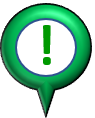**Note:**

- That   $\phi_i \;\ldotp \phi_i^T$   is a $P\times P$ matrix.  

- So $\left\lbrack H\left(s\right)\right\rbrack$ is a summation of these $P\times P$ matrices.

## Pull this back to our 2-dof system:

 Assume for our 2-dof system that:

- 
$${\vec{\phi} }_1 =\left\lbrack \begin{array}{c}
a\\
b
\end{array}\right\rbrack \;\;\;\;\Longrightarrow \;\;\;\;\;{\vec{\phi} }_1 \ldotp {\left(\;\;{\vec{\phi} }_1 \right)}^T \;=\;\left\lbrack \begin{array}{cc}
a^2  & a\ldotp b\\
a\ldotp b & b^2 
\end{array}\right\rbrack$$


- 
$${\vec{\phi} }_2 =\left\lbrack \begin{array}{c}
c\\
d
\end{array}\right\rbrack \;\;\;\;\Longrightarrow \;\;\;\;\;{\vec{\phi} }_2 \ldotp {\left(\;\;{\vec{\phi} }_2 \right)}^T \;=\;\left\lbrack \begin{array}{cc}
c^2  & c\ldotp d\\
c\ldotp d & d^2 
\end{array}\right\rbrack$$


For our **2-dof** system ... let's just expand out our expression for $H\left(s\right)$ :

- 
$$\left\lbrack H\left(s\right)\right\rbrack \;\;=\;\left\lbrack \begin{array}{cc}
H_{11} \left(s\right) & H_{12} \left(s\right)\;\\
H_{21} \left(s\right) & H_{22} \left(s\right)
\end{array}\right\rbrack \;\;=\;\;\frac{\left\lbrack \phi_1 \;\ldotp \phi_1^T \right\rbrack }{s^2 \;\;+\;2\ldotp \zeta_1 \ldotp \omega_{\mathrm{n1}} \ldotp s\;\;+\;\omega_{\mathrm{n1}}^2 }\;\;\;+\;\;\;\;\frac{\left\lbrack \phi_2 \;\ldotp \phi_2^T \right\rbrack }{s^2 \;\;+\;2\ldotp \zeta_2 \ldotp \omega_{\mathrm{n2}} \ldotp s\;\;+\;\omega_{\mathrm{n2}}^2 }$$
 

- 
$$\left\lbrack H\left(s\right)\right\rbrack \;\;=\;\left\lbrack \begin{array}{cc}
H_{11} \left(s\right) & H_{12} \left(s\right)\;\\
H_{21} \left(s\right) & H_{22} \left(s\right)
\end{array}\right\rbrack \;\;=\;\;\;\;\;\frac{\left\lbrack \begin{array}{cc}
a^2  & a\ldotp b\\
a\ldotp b & b^2 
\end{array}\right\rbrack }{s^2 \;\;+\;2\ldotp \zeta_1 \ldotp \omega_{\mathrm{n1}} \ldotp s\;\;+\;\omega_{\mathrm{n1}}^2 }\;\;\;\;\;+\;\;\;\;\;\;\frac{\;\left\lbrack \begin{array}{cc}
c^2  & c\ldotp d\\
c\ldotp d & d^2 
\end{array}\right\rbrack }{s^2 \;\;+\;2\ldotp \zeta_2 \ldotp \omega_{\mathrm{n2}} \ldotp s\;\;+\;\omega_{\mathrm{n2}}^2 }\;\;\;\;\;\;\;\;\;\;\;$$


Form a common denominator and add these things together:

- 
$$\left\lbrack H\left(s\right)\right\rbrack \;\;=\;\left\lbrack \begin{array}{cc}
H_{11} \left(s\right) & H_{12} \left(s\right)\;\\
H_{21} \left(s\right) & H_{22} \left(s\right)
\end{array}\right\rbrack \;\;=\;\;\;\;\;\;\frac{\left\lbrace \left\lbrack \begin{array}{cc}
a^2  & a\ldotp b\\
a\ldotp b & b^2 
\end{array}\right\rbrack \ldotp \left(s^2 \;\;+\;2\ldotp \zeta_2 \ldotp \omega_{\mathrm{n2}} \ldotp s\;\;+\;\omega_{\mathrm{n2}}^2 \right)\right\rbrace \;\;\;\;+\;\;\;\;\;\left\lbrace \left\lbrack \begin{array}{cc}
c^2  & c\ldotp d\\
c\ldotp d & d^2 
\end{array}\right\rbrack \ldotp \left(s^2 \;\;+\;2\ldotp \zeta_1 \ldotp \omega_{\mathrm{n1}} \ldotp s\;\;+\;\omega_{\mathrm{n1}}^2 \right)\right\rbrace }{\left(s^2 \;\;+\;2\ldotp \zeta_1 \ldotp \omega_{\mathrm{n1}} \ldotp s\;\;+\;\omega_{\mathrm{n1}}^2 \right)\ldotp \left(s^2 \;\;+\;2\ldotp \zeta_2 \ldotp \omega_{\mathrm{n2}} \ldotp s\;\;+\;\omega_{\mathrm{n2}}^2 \right)}\;\;\;\;\;\;\;\;\;\;\;$$


So the 4 **SYSTEM poles** are:

- $\lambda_1 \;\;=\;\;-\zeta_1 \ldotp {\omega_{\mathrm{n1}} \;\;\;+\;\;\;j\ldotp \omega_{\mathrm{n1}} \ldotp \sqrt{1-{\zeta_1 }^2 }}_{\;}$     ***and***     ${\bar{\lambda} }_1 \;\;=\;-\zeta_1 \ldotp {\omega_{\mathrm{n1}} \;\;\;-\;\;\;\;j\ldotp \omega_{\mathrm{n1}} \ldotp \sqrt{1-{\zeta_1 }^2 }}_{\;}$

- $\lambda_2 \;\;=\;\;-\zeta_2 \ldotp {\omega_{\mathrm{n2}} \;\;\;+\;\;\;j\ldotp \omega_{\mathrm{n2}} \ldotp \sqrt{1-{\zeta_2 }^2 }}_{\;}$     ***and***     ${\bar{\lambda} }_2 \;\;=\;-\zeta_2 \ldotp {\omega_{\mathrm{n2}} \;\;\;-\;\;\;\;j\ldotp \omega_{\mathrm{n2}} \ldotp \sqrt{1-{\zeta_2 }^2 }}_{\;}$

**What about the ZEROS ?**

We don't have "system" zeros, rather each element of the transfer function matrix will have it's own zeros.  For example the ZEROS of $H_{11} \left(s\right)$ are found from solving the equation:

- 
$$H_{11} \left(s\right)\;\;=\;\;\;0\;\;\;=\left\lbrace a^2 \;\ldotp \left(s^2 \;\;+\;2\ldotp \zeta_2 \ldotp \omega_{\mathrm{n2}} \ldotp s\;\;+\;\omega_{\mathrm{n2}}^2 \right)\right\rbrace \;\;\;\;+\;\;\;\;\;\left\lbrace c^2 \;\ldotp \left(s^2 \;\;+\;2\ldotp \zeta_1 \ldotp \omega_{\mathrm{n1}} \ldotp s\;\;+\;\omega_{\mathrm{n1}}^2 \right)\right\rbrace$$


**And one more thing:**

Let's focus on $H_{11} \left(s\right)$ and $H_{21} \left(s\right)$.  From our derivation above, we can write:

- 
$$H_{11} \left(s\right)\;\;=\;\;\;\;\frac{a^2 }{s^2 \;\;+\;2\ldotp \zeta_1 \ldotp \omega_{\mathrm{n1}} \ldotp s\;\;+\;\omega_{\mathrm{n1}}^2 }\;\;\;\;\;+\;\;\;\;\;\;\frac{\;c^2 }{s^2 \;\;+\;2\ldotp \zeta_2 \ldotp \omega_{\mathrm{n2}} \ldotp s\;\;+\;\omega_{\mathrm{n2}}^2 }$$


- 
$$H_{21} \left(s\right)\;\;=\;\;\;\;\frac{a\ldotp b}{s^2 \;\;+\;2\ldotp \zeta_1 \ldotp \omega_{\mathrm{n1}} \ldotp s\;\;+\;\omega_{\mathrm{n1}}^2 }\;\;\;\;\;+\;\;\;\;\;\;\frac{\;c\ldotp d}{s^2 \;\;+\;2\ldotp \zeta_2 \ldotp \omega_{\mathrm{n2}} \ldotp s\;\;+\;\omega_{\mathrm{n2}}^2 }$$


And we saw in the "Modal Model Representation" (see [`HERE`](matlab:  open  bh_Modal.APPENDIX_01_Modal_Model_Representation)) that each Second Order Section can be expanded as a sum of two 1st order sections.  So $H_{11} \left(s\right)$ can be written as:

- 
$$H_{11} \left(s\right)\;\;\;=\;\;\frac{R_{11,1} }{s-\lambda_1 }\;\;\;+\;\;\;\frac{{\bar{R} }_{11,1} }{s-{\bar{\lambda} }_1 }\;\;+\;\;\;\frac{R_{11,2} }{s-\lambda_2 }\;\;\;+\;\;\;\frac{{\bar{R} }_{11,2} }{s-{\bar{\lambda} }_2 }$$


When we reform the second order sections it produces:

- 
$$H_{11} \left(s\right)\;\;=\;\;\;\;\frac{-2\ldotp \mathrm{imag}\left(R_{11,1} \right)\ldotp \omega_{\mathrm{n1}} \ldotp \sqrt{1-{\zeta_1 }^2 }}{s^2 \;\;+\;2\ldotp \zeta_1 \ldotp \omega_{\mathrm{n1}} \ldotp s\;\;+\;\omega_{\mathrm{n1}}^2 }\;\;\;\;\;+\;\;\;\;\;\;\frac{-2\ldotp \mathrm{imag}\left(R_{11,2} \right)\ldotp \omega_{\mathrm{n2}} \ldotp \sqrt{1-{\zeta_2 }^2 }}{s^2 \;\;+\;2\ldotp \zeta_2 \ldotp \omega_{\mathrm{n2}} \ldotp s\;\;+\;\omega_{\mathrm{n2}}^2 }$$


A similar expression can be formed for $H_{21} \left(s\right)$:

- 
$$H_{21} \left(s\right)\;\;=\;\;\;\;\frac{-2\ldotp \mathrm{imag}\left(R_{21,1} \right)\ldotp \omega_n 1\ldotp \sqrt{1-{\zeta_1 }^2 }}{s^2 \;\;+\;2\ldotp \zeta_1 \ldotp \omega_{\mathrm{n1}} \ldotp s\;\;+\;\omega_{\mathrm{n1}}^2 }\;\;\;\;\;+\;\;\;\;\;\;\frac{-2\ldotp \mathrm{imag}\left(R_{21,2} \right)\ldotp \omega_{\mathrm{n2}} \ldotp \sqrt{1-{\zeta_2 }^2 }}{s^2 \;\;+\;2\ldotp \zeta_2 \ldotp \omega_{\mathrm{n2}} \ldotp s\;\;+\;\omega_{\mathrm{n2}}^2 }$$


So when we compare the **NUMERATORS** of each second order section we see that the normal mode shape data is encoded into the **RESIDUE** of the first order sections, i.e.:

So ? - So if you extract the RESIDUES you have the normal mode shape vectors to within scaling constants $q$, i.e.:

- $a\ldotp \left\lbrack \begin{array}{c}
a\\
b
\end{array}\right\rbrack \;=\;\;q_1 \ldotp \mathrm{imag}\left(\left\lbrack \begin{array}{c}
R_{11,1} \\
R_{21,1} 
\end{array}\right\rbrack \right)$      and       $c\ldotp \left\lbrack \begin{array}{c}
c\\
d
\end{array}\right\rbrack =q_2 \ldotp \mathrm{imag}\left(\left\lbrack \begin{array}{c}
R_{11,2} \\
R_{21,2} 
\end{array}\right\rbrack \right)$

i.e.:

- $a\;\ldotp \;{\vec{\phi} }_1 \;=\;q_1 \ldotp \mathrm{imag}\left(\left\lbrack \begin{array}{c}
R_{11,1} \\
R_{21,1} 
\end{array}\right\rbrack \right)$      and     $c\ldotp {\vec{\phi} }_2 =q_2 \ldotp \mathrm{imag}\left(\left\lbrack \begin{array}{c}
R_{11,2} \\
R_{21,2} 
\end{array}\right\rbrack \right)$

## State Space representation:

Our Mechanical equations of motion can also be expressed as a $1^{\mathrm{st}}$ order system  - usually referred to as a State Space representation.

First, recall our damped Mechanical equations of motion:

- $M \ddot{x}  +   C \dot{x}  +  Kx = f$      where   $x \in R^{P\times1}$    and   $f \in R^{P\times1}$

These Mechanical equations of motion can be expressed as the $1^{\mathrm{st}}$ order system :

- $\pmatrix{
\ddot{x} \cr
\dot{x} \cr
}$ = $\pmatrix{
-M^{-1}C & -M^{-1}K \cr
I_{P \times P} & 0_{P \times P} \cr
}$$. \pmatrix{
\dot{x} \cr
x \cr
}$  +  $\pmatrix{
M^{-1} \cr
0_{P \times P} \cr
}.f$

Which has the form:

- $\dot{z} = A . z + B.u$    where:  $z\;=\left\lbrack \begin{array}{c}
{\dot{x} }_1 \\
{\dot{x} }_2 \\
x_1 \\
x_2 
\end{array}\right\rbrack \;\;=\;\;\left\lbrack \begin{array}{c}
\dot{\bm{x}} \\
\bm{x}
\end{array}\right\rbrack \;\in \;\;R^{2P\times 1}$   **and**    $B = \pmatrix{
M^{-1} \cr
0_{P \times P} \cr
}$    **and**    $A = \pmatrix{
-M^{-1}{C} & -M^{-1}{K}\cr
I_{P \times P} & 0_{P \times P} \cr
}$   **and**   $u=f$

And let's just measure the displacements such that

- $y=\;\left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack \;\;\;\;\Longrightarrow \;\;\;\;\;$$y=G\ldotp z\;+\;D\ldotp u$     where    $G=\;\left\lbrack \begin{array}{cc}
0_{P\times P}  & I_{P\times P} 
\end{array}\right\rbrack$    and  $D=0_{P\times P}$

**Note:  **the state space system represented by the matrices $A,B,G,D$ is equivalent to the Mechanical Transfer Function representation derived earlier. And in fact we can convert the State space system into a transfer function system also (recall $D=0_{P\times P}$):

- 
$$\dot{z} =A\ldotp z\;+B\ldotp u\;\;\;\;\;\;\Longrightarrow \;\;\;s\ldotp Z\left(s\right)=A\ldotp Z\left(s\right)+B\ldotp F\left(s\right)\;\;\Longrightarrow \;\;\left(s\ldotp I-A\right)\ldotp Z\left(s\right)=B\ldotp F\left(s\right)$$
 

- 
$$y=G\ldotp z\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Longrightarrow \;\;\;\;\;Y\left(s\right)=X\left(s\right)=G\ldotp Z\left(s\right)\;=\;G\ldotp {\left(s\ldotp I-A\right)}^{-1} \ldotp B\ldotp F\left(s\right)$$


So

- 
$$X\left(s\right)=\left\lbrack G\ldotp {\left(s\ldotp I-A\right)}^{-1} \ldotp B\right\rbrack \ldotp F\left(s\right)$$


- 
$$X\left(s\right)=\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left\lbrack H\left(s\right)\right\rbrack \;\ldotp F\left(s\right)$$


## Let's explore our 2-dof Mechanical system

Clear our workspace

clear

So define the parameter values for our Mechanical system

k1 = 1e4;  % (N/m)
m1 = 1e2;  % (kg)
k2 = 1e3;  % (N/m)
m2 = 5;    % (kg)

M_MAT_fh = @(m1,m2)  [m1, 0; ...
                       0, m2 ];


K_MAT_fh = @(k1,k2)  [ (k1+k2), (-k2);
                         (-k2),  (k2)];

% add a "tiny" bit of damping
C_MAT_fh = @(K) 1e-4* K;

Define the Mechanical system matrices

M = M_MAT_fh(m1,m2);
K = K_MAT_fh(k1,k2);
C = C_MAT_fh(K);

### Explore the Eigenvalue problem

- $M\ldotp \ddot{x} \;+\;K\ldotp x=0$  where $x\;\in R^{\;P\times 1}$

And let's look for a harmonic solution of the form:

- 
$$x\left(t\right)=\;\;\;\;\;\;v\ldotp e^{\;i\ldotp \omega \;\ldotp t}$$


- 
$$\dot{x} \left(t\right)=\;\;\;\;\;\;\;\;i\ldotp \omega \;\ldotp x\left(t\right)$$


- 
$$\ddot{x} \left(t\right)=\;-1\ldotp \omega^2 \ldotp x\left(t\right)\;$$


Then our ODE becomes:

- 
$$\left\lbrack -M\ldotp \omega^2 \;\;+\;\;K\right\rbrack \ldotp x\left(t\right)\;=\;0$$


- 
$$K\ldotp x\left(t\right)=M\ldotp x\left(t\right)\ldotp \omega^2$$


- 
$$M^{-1} \ldotp K\ldotp x\left(t\right)=\omega^2 \ldotp x\left(t\right)$$


- 
$$M^{-1} \ldotp K\ldotp v\ldotp e^{\;i\ldotp \omega \;\ldotp t} =\omega^2 \ldotp v\ldotp e^{\;i\ldotp \omega \;\ldotp t}$$


- 
$$M^{-1} \ldotp K\ldotp v=\omega^2 \ldotp v$$


- $A\ldotp v=\lambda \;\ldotp v$       where  $\lambda =\omega^2$  and $A=M^{-1} \ldotp K$

[eVec, eVal] = eig(  inv(M) * K  );

So the Mechanical UNdamped  Natural frequencies are

- $\omega_n \;\;=\;\;\sqrt{\;\;\lambda \;\;\;}$   (rad/sec)

wn = sqrt(diag(eVal))

wn =     9.5685
   14.7798


**Sort the eigenvector columns based on the ascending order of the eigenvalues:**

[~,ind] = sort( diag(eVal) );

eVec    = eVec(:, ind);
eVal    = eVal(:, ind);

Since $M=M^T$  and  $K=K^T$ then let's **normalize** the eigenvectors such that:  

-   
$$I\;\;={\;\;V}^T \ldotp M\ldotp V$$


tmp         = eVec.' * M * eVec;
tmp_row     =  diag(tmp)';
eVec_PHI    = eVec ./ sqrt( tmp_row );

Im_mat      = eVec_PHI.' * M * eVec_PHI;

Confirm the eigenvector normalization with a plot

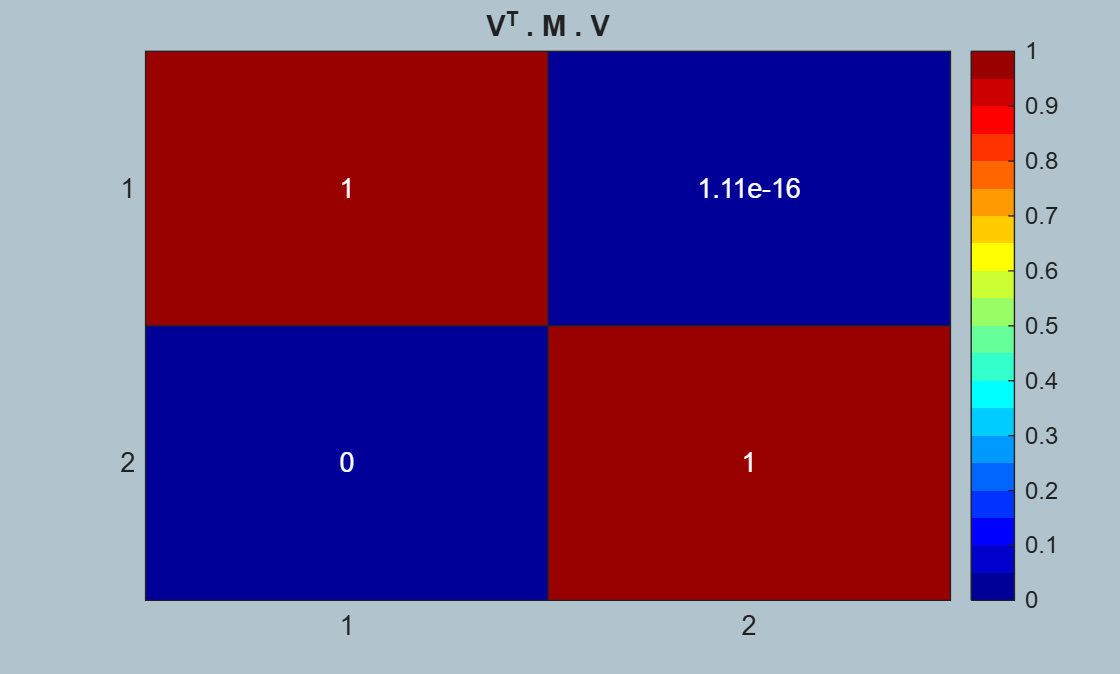

figure;
    heatmap(Im_mat, "Colormap", jet(20) );
        title("V^T . M . V")

And the above eigenvector scaling should also give us:

- 
$$\;\Omega^{2\;} =\;\;V^T \ldotp K\ldotp V$$


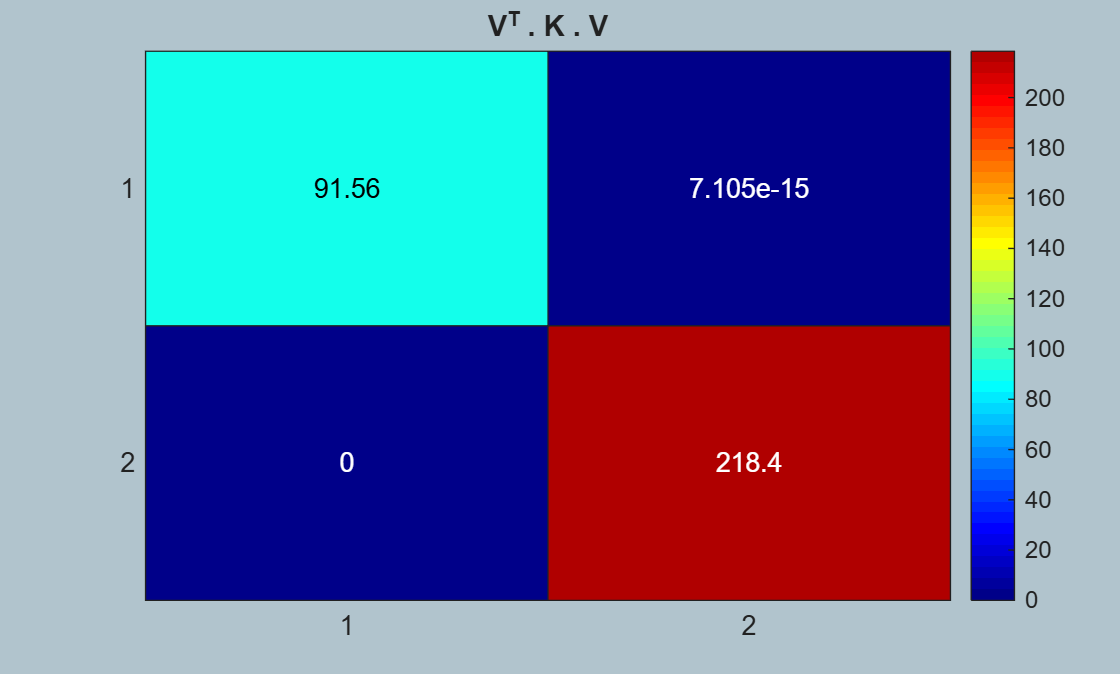

w2_mat      = eVec_PHI.' * K * eVec_PHI;

figure;
    heatmap(w2_mat, "Colormap", jet(50) );
        title("V^T . K . V")

So summarize our UNdamped Mode shapes:

fprintf("\n ... UNdamped Mode shape vectors are:")


 ... UNdamped Mode shape vectors are:

       
        eVec_PHI        

eVec_PHI =    -0.0924    0.0381
   -0.1705   -0.4134


### Define the State Space system

- $\pmatrix{
\ddot{x} \cr
\dot{x} \cr
}$ = $\pmatrix{
-M^{-1}C & -M^{-1}K \cr
I_{P \times P} & 0_{P \times P} \cr
}$$. \pmatrix{
\dot{x} \cr
x \cr
}$  +  $\pmatrix{
M^{-1} \cr
0_{P \times P} \cr
}.f$

- $y=G\ldotp z\;+\;D\ldotp u$     where    $G=\;\left\lbrack \begin{array}{cc}
0_{P\times P}  & I_{P\times P} 
\end{array}\right\rbrack$    and  $D=0_{P\times P}$

A = [-inv(M)*C, -inv(M)*K;  eye(2), zeros(2)];
B = [inv(M);zeros(2)];
G = [zeros(2), eye(2)];
D = zeros(2);

H_ss = ss(A,B,G,D,0,"Outputname",{'x1','x2'},"InputName",{'f1','f2'})


H_ss =
 
  A = 
           x1      x2      x3      x4
   x1  -0.011   0.001    -110      10
   x2    0.02   -0.02     200    -200
   x3       1       0       0       0
   x4       0       1       0       0
 
  B = 
         f1    f2
   x1  0.01     0
   x2     0   0.2
   x3     0     0
   x4     0     0
 
  C = 
       x1  x2  x3  x4
   x1   0   0   1   0
   x2   0   0   0   1
 
  D = 
       f1  f2
   x1   0   0
   x2   0   0
 
Continuous-time state-space model.


### What are the system POLES 

Extract the SYSTEM poles

- see the DOC for [`damp`](matlab: doc damp)

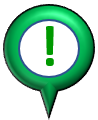 These should be:

- $\lambda_1 \;\;=\;\;-\zeta_1 \ldotp {\omega_{\mathrm{n1}} \;\;\;+\;\;\;j\ldotp \omega_{\mathrm{n1}} \ldotp \sqrt{1-{\zeta_1 }^2 }}_{\;}$     ***and***     ${\bar{\lambda} }_1 \;\;=\;-\zeta_1 \ldotp {\omega_{\mathrm{n1}} \;\;\;-\;\;\;\;j\ldotp \omega_{\mathrm{n1}} \ldotp \sqrt{1-{\zeta_1 }^2 }}_{\;}$

- $\lambda_2 \;\;=\;\;-\zeta_2 \ldotp {\omega_{\mathrm{n2}} \;\;\;+\;\;\;j\ldotp \omega_{\mathrm{n2}} \ldotp \sqrt{1-{\zeta_2 }^2 }}_{\;}$     ***and***     ${\bar{\lambda} }_2 \;\;=\;-\zeta_2 \ldotp {\omega_{\mathrm{n2}} \;\;\;-\;\;\;\;j\ldotp \omega_{\mathrm{n2}} \ldotp \sqrt{1-{\zeta_2 }^2 }}_{\;}$

[wn, zeta, p]  = damp(H_ss);
array2table([(wn/(2*pi)), wn, zeta, p], "VariableNames",["Fn_Hz", "Undamped_wn","DampingRatio","poles"])

ans = 4×4 table
    Fn_Hz     Undamped_wn    DampingRatio          poles       
    ______    ___________    ____________    __________________

    1.5229      9.5685        0.00047843     -0.0045779+9.5685i
    1.5229      9.5685        0.00047843     -0.0045779-9.5685i
    2.3523       14.78        0.00073899      -0.010922+14.78i 
    2.3523       14.78        0.00073899      -0.010922-14.78i 

	Get insights using Copilot


### What does $H_{11} \left(s\right)$ actually look like ?

THE_TF_H11 = tf( H_ss(1,1) )


THE_TF_H11 =
 
  From input "f1" to output "x1":
         0.01 s^2 + 0.0002 s + 2
  --------------------------------------
  s^4 + 0.031 s^3 + 310 s^2 + 4 s + 2e04
 
Continuous-time transfer function.


### What is (for example) the ZEROS of $H_{11} \left(s\right)$

Extract the zeros for $H_{11} \left(s\right)$

array2table( zero(THE_TF_H11), "VariableNames",["zeros(H11)"])

ans = 2×1 table
     zeros(H11)  
    _____________

    -0.01+14.142i
    -0.01-14.142i

	Get insights using Copilot


### Plot the Frequency Response  (NO Phase wrapping)

my_plot_opts               = bodeoptions;
my_plot_opts.PhaseWrapping = "off";
my_plot_opts.FreqUnits     = "Hz";

Let's just plot $H_{11} \left(s\right)$

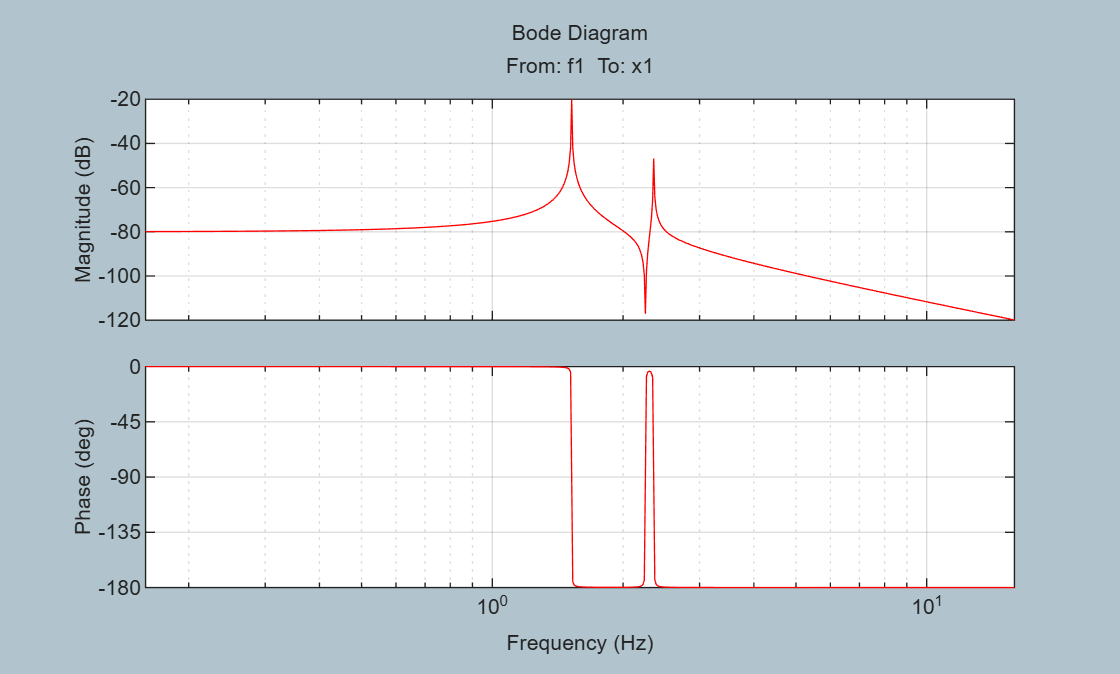

figure;  bodeplot(H_ss(1,1),'-r', {1, 1e2}, my_plot_opts); grid on

% figure;  bodeplot(H_ss(1,2),'-b', {1, 1e2}, my_plot_opts); grid on
% figure;  bodeplot(H_ss(2,1),'-m', {1, 1e2}, my_plot_opts); grid on
% figure;  bodeplot(H_ss(2,2),'-k', {1, 1e2}, my_plot_opts); grid on

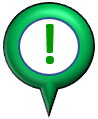 Some observations

- The ZEROS of $H_{11} \left(s\right)$ are currently at the EXCITATION frequency $\;\omega =14\ldotp 1421$(rad/sec)  (== 2.25 Hz) - as shown by the **ANTI resonance** in the bode plot

### Explore First and Second Order Section representation

Recall our transfer function for $H_{11} \left(s\right)$ can be expressed as a sum of Second order sections:

- 
$$H_{11} \left(s\right)\;\;=\;\;\;\;\frac{a^2 }{s^2 \;\;+\;2\ldotp \zeta_1 \ldotp \omega_{\mathrm{n1}} \ldotp s\;\;+\;\omega_{\mathrm{n1}}^2 }\;\;\;\;\;+\;\;\;\;\;\;\frac{\;c^2 }{s^2 \;\;+\;2\ldotp \zeta_2 \ldotp \omega_{\mathrm{n2}} \ldotp s\;\;+\;\omega_{\mathrm{n2}}^2 }$$


And ... it can also be expressed as a sum of First order sections

- 
$$H_{11} \left(s\right)\;\;\;=\;\;\frac{R_{11,1} }{s-\lambda_1 }\;\;\;+\;\;\;\frac{{\bar{R} }_{11,1} }{s-{\bar{\lambda} }_1 }\;\;+\;\;\;\frac{R_{11,2} }{s-\lambda_2 }\;\;\;+\;\;\;\frac{{\bar{R} }_{11,2} }{s-{\bar{\lambda} }_2 }$$


where:

- $\lambda_1 \;\;=\;\;-\zeta_1 \ldotp {\omega_{\mathrm{n1}} \;\;\;+\;\;\;j\ldotp \omega_{\mathrm{n1}} \ldotp \sqrt{1-{\zeta_1 }^2 }}_{\;}$     ***and***     ${\bar{\lambda} }_1 \;\;=\;-\zeta_1 \ldotp {\omega_{\mathrm{n1}} \;\;\;-\;\;\;\;j\ldotp \omega_{\mathrm{n1}} \ldotp \sqrt{1-{\zeta_1 }^2 }}_{\;}$

- $\lambda_2 \;\;=\;\;-\zeta_2 \ldotp {\omega_{\mathrm{n2}} \;\;\;+\;\;\;j\ldotp \omega_{\mathrm{n2}} \ldotp \sqrt{1-{\zeta_2 }^2 }}_{\;}$     ***and***     ${\bar{\lambda} }_2 \;\;=\;-\zeta_2 \ldotp {\omega_{\mathrm{n2}} \;\;\;-\;\;\;\;j\ldotp \omega_{\mathrm{n2}} \ldotp \sqrt{1-{\zeta_2 }^2 }}_{\;}$

Right now we have the transfer function for $H_{11} \left(s\right)$ :

THE_TF_H11


THE_TF_H11 =
 
  From input "f1" to output "x1":
         0.01 s^2 + 0.0002 s + 2
  --------------------------------------
  s^4 + 0.031 s^3 + 310 s^2 + 4 s + 2e04
 
Continuous-time transfer function.


So , convert $H_{11} \left(s\right)$ into the sum of first order sections:

-  See the doc page for:  [`residue()`](matlab:  doc residue)

[tmp_num, tmp_den]     = tfdata(THE_TF_H11, 'v');

[tmp_r, tmp_p, tmp_k]  =  residue(tmp_num, tmp_den)

tmp_r = 1.0e-03 *

  -0.0000 - 0.0492i
  -0.0000 + 0.0492i
   0.0000 - 0.4466i
   0.0000 + 0.4466i


tmp_p =   -0.0109 +14.7798i
  -0.0109 -14.7798i
  -0.0046 + 9.5685i
  -0.0046 - 9.5685i



tmp_k =

     []



Keep POSITIVE imaginary parts of the poles and residues and sort from SMALL to BIG

tmp_ind     = find(imag(tmp_p) > 0);

tmp_p       = tmp_p(tmp_ind);
tmp_r       = tmp_r(tmp_ind);

[~,tmp_ind] = sort(imag(tmp_p));

tmp_p       = tmp_p(tmp_ind);
tmp_r       = tmp_r(tmp_ind);

Now reconstruct the Seconder order sections from the First order sections

- 
$$H_{11} \left(s\right)\;\;\;=\;\;\frac{R_{11,1} }{s-\lambda_1 }\;\;\;+\;\;\;\frac{{\bar{R} }_{11,1} }{s-{\bar{\lambda} }_1 }\;\;+\;\;\;\frac{R_{11,2} }{s-\lambda_2 }\;\;\;+\;\;\;\frac{{\bar{R} }_{11,2} }{s-{\bar{\lambda} }_2 }$$


H_11_part_1 = tf(     tmp_r(1),  [1,      -1*tmp_p(1)])   + ...
              tf(conj(tmp_r(1)), [1, -1*conj(tmp_p(1))])


H_11_part_1 =
 
   9.537e-20 s + 0.008546
  ------------------------
  s^2 + 0.009156 s + 91.56
 
Continuous-time transfer function.



H_11_part_2 = tf(     tmp_r(2),  [1,       -1*tmp_p(2)])   + ...
              tf(conj(tmp_r(2)), [1, -1*conj(tmp_p(2))])


H_11_part_2 =
 
  -9.502e-20 s + 0.001454
  -----------------------
  s^2 + 0.02184 s + 218.4
 
Continuous-time transfer function.


Extract the numerator of each part

- 
$$H_{11} \left(s\right)\;\;=\;\;\;\;\frac{a^2 }{s^2 \;\;+\;2\ldotp \zeta_1 \ldotp \omega_{\mathrm{n1}} \ldotp s\;\;+\;\omega_{\mathrm{n1}}^2 }\;\;\;\;\;+\;\;\;\;\;\;\frac{\;c^2 }{s^2 \;\;+\;2\ldotp \zeta_2 \ldotp \omega_{\mathrm{n2}} \ldotp s\;\;+\;\omega_{\mathrm{n2}}^2 }$$


[H_11_part_1_NUMER,~] = tfdata(H_11_part_1, 'v');
H_11_part_1_NUMER     = H_11_part_1_NUMER(end);

[H_11_part_2_NUMER,~] = tfdata(H_11_part_2, 'v');
H_11_part_2_NUMER     = H_11_part_2_NUMER(end);

should_be_a2_and_c2   = [H_11_part_1_NUMER,  H_11_part_2_NUMER]

should_be_a2_and_c2 =     0.0085    0.0015


So how do these values compare to the normalized MODE shapes ?

- $\Phi \;\;\;=\;\left\lbrack \begin{array}{cc}
{\vec{\;\phi } }_1 \; & \;{\vec{\phi} }_2 \;
\end{array}\right\rbrack \;=\;\left\lbrack \begin{array}{cc}
a & c\\
b & d
\end{array}\right\rbrack$   where   $I\;\;=\Phi^T \ldotp M\ldotp \Phi$  and   $\;\Omega^{2\;} =\;\;\Phi^T \ldotp K\ldotp \Phi$

So compute $a^2$ and $c^2$

actual_a2_and_c2 = [ eVec_PHI(1,1)^2,  eVec_PHI(1,2)^2 ] 

actual_a2_and_c2 =     0.0085    0.0015


Similarly, do you recall in our "Background" discussion at the start of this script, we had the table:

So let's check that too:

ALSO_should_be_a2_and_c2 = [-2*imag(tmp_r(1))*imag(tmp_p(1)), ...
                            -2*imag(tmp_r(2))*imag(tmp_p(2)) ]

ALSO_should_be_a2_and_c2 =     0.0085    0.0015


# Let's Simulate and do a Modal system identification

Experiment configuration:

- We'll do a SIMO test, where the excitation is only provided by $F_1$

- The excitation force $F_1$ will be a Chirp burst that sweeps across frequencies 0.1 Hz to 10 Hz

- We'll use the [`lsim()`](matlab: doc lsim) function to simulate our system

- We'll use the [`chirp()`](matlab:  doc chirp) function to create our chirp excitation signal

- We'll use a sampling time of $\Delta t=\frac{1}{100}$

- The whole experiment will run for 300 seconds

OK: generate the Excitation matrix

my_config_S.T_dur = 300;
my_config_S.dt    = 1/100;
my_config_S.Fs_Hz = 1/my_config_S.dt;

t_col = [0:my_config_S.dt:my_config_S.T_dur]';

U_mat = [chirp(t_col, 0, t_col(end), 10),   zeros(size(t_col))];

Simulate the system

Y_MAT = lsim(H_ss, U_mat, t_col);

## Estimate the Systems FRF:

- see DOC for [`modalfrf()`](matlab:  doc modalfrf) 

- **NOTE:**  using an ***overlap*** with each "block" of data gives really good results

THE_WINDOW = hann( floor(length(U_mat(:,1))/3)  );
%THE_WINDOW = ones( floor(length(U_mat(:,1))/3),1  );
n_OVERLAP  =  length(THE_WINDOW)/2;

[all_frf, all_f, tmp_coh] = modalfrf(U_mat(:,1), Y_MAT, my_config_S.Fs_Hz, THE_WINDOW, n_OVERLAP, Sensor="dis");

whos  all_frf  all_f

  Name            Size             Bytes  Class     Attributes

  all_f        5001x1              40008  double              
  all_frf      5001x2             160032  double    complex   



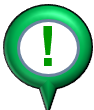 **NOTE:**  the frequency vector `all_f` (in Hz) that is returned only includes frequencies up to the NYQUIST frequency

all_f(end)

ans = 50

## Specify the Frequency range of interest

%roi.range_Hz = [2, 3];
roi.range_Hz = [1, 4];
tmp_ind      = find( (all_f > roi.range_Hz(1)) & (all_f < roi.range_Hz(2))  );

roi.f_hz_col = all_f(tmp_ind);
roi.frf      = all_frf(tmp_ind, 1);
roi.frf_all  = all_frf(tmp_ind, :);

Plot the **measured FRF** relating the Excitation to the first measurement station

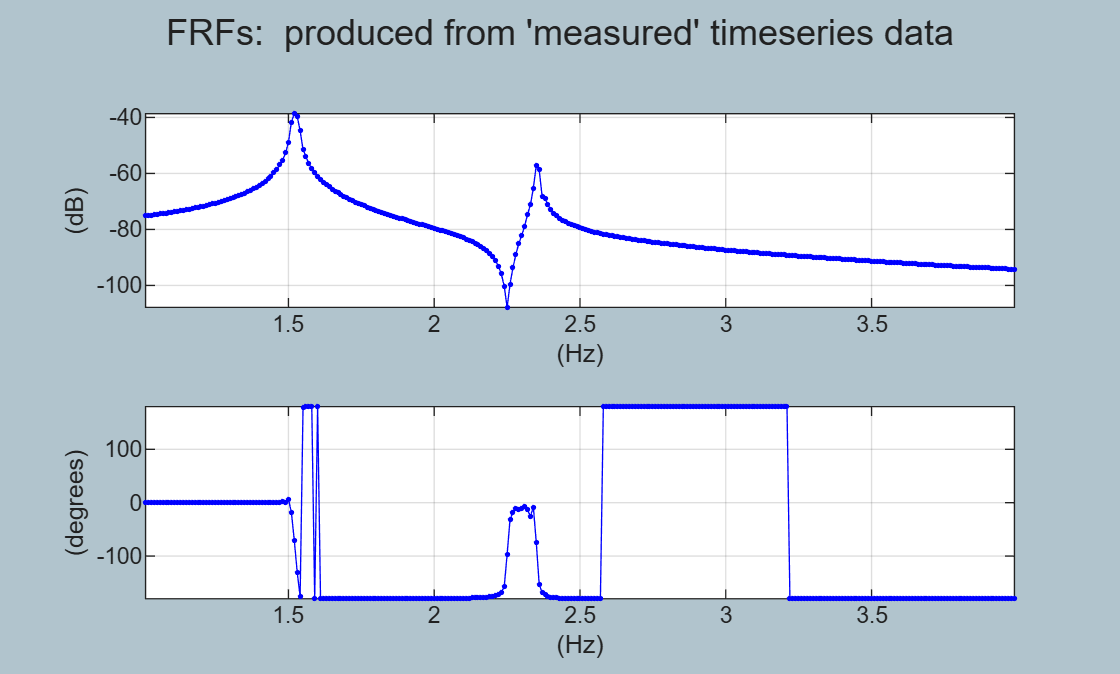

figure;
  hax(1) = subplot(2,1,1); 
       plot(roi.f_hz_col, 20*log10( abs(roi.frf)), "-b.", "DisplayName","MEAS")
           grid on; axis tight
           xlabel("(Hz)");   ylabel("(dB)");

  hax(2) = subplot(2,1,2); 
       plot(roi.f_hz_col, rad2deg( angle(roi.frf) ), "-b.")
           grid on; axis tight
           xlabel("(Hz)");  ylabel("(degrees)")   
  sgtitle("FRFs:  produced from 'measured' timeseries data")         

## Compare the Measured FRF against the True plant FRF

First let's evaluat our golden reference transfer function at the frequencies of interest

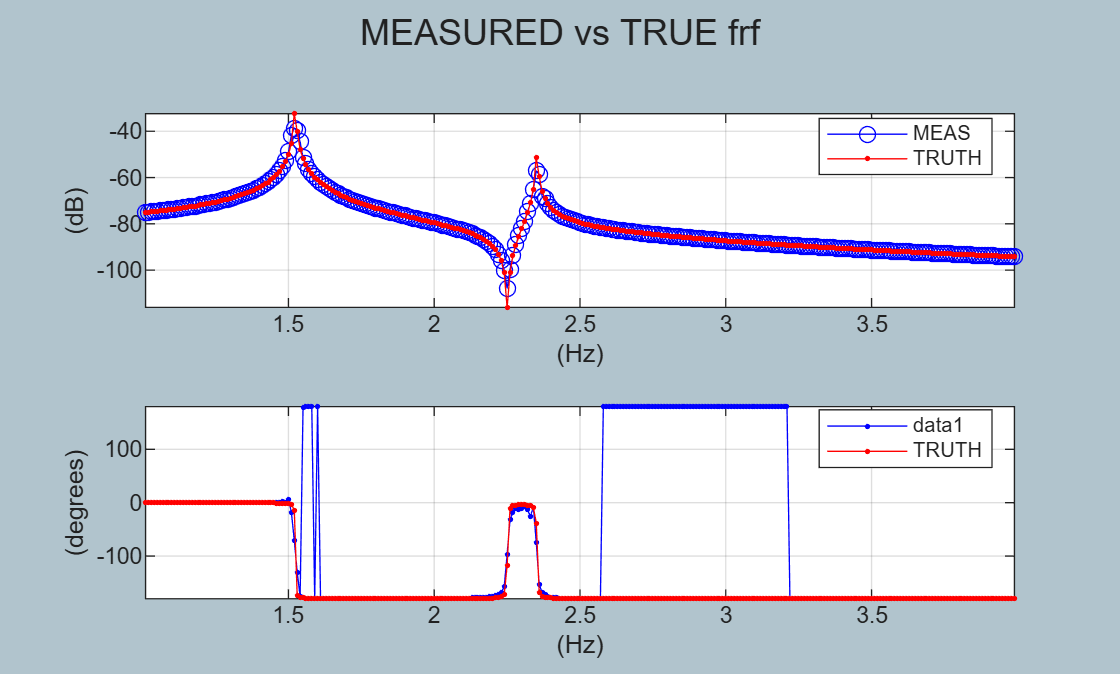

H11_FRF_GOLDEN_REF = freqresp(THE_TF_H11, roi.f_hz_col,"Hz");
H11_FRF_GOLDEN_REF = squeeze(H11_FRF_GOLDEN_REF);
figure;
  hax(1) = subplot(2,1,1); 
       plot(roi.f_hz_col, 20*log10( abs(roi.frf)), "-bo", "DisplayName","MEAS")
           grid on; axis tight
           xlabel("(Hz)");   ylabel("(dB)");
       hold on
       plot(roi.f_hz_col, 20*log10( abs(H11_FRF_GOLDEN_REF)), "-r.", "DisplayName","TRUTH") 
           legend("Location","best")

  hax(2) = subplot(2,1,2); 
       plot(roi.f_hz_col, rad2deg( angle(roi.frf) ), "-b.")
           grid on; axis tight
           xlabel("(Hz)");  ylabel("(degrees)")   
       hold on
       plot(roi.f_hz_col, rad2deg( angle(H11_FRF_GOLDEN_REF) ), "-r.", "DisplayName","TRUTH")
             legend("Location","best")

  sgtitle("MEASURED vs TRUE frf")     

## Let's extract our MODAL properties from the measured FRFs

try_it_FitMethod = "lsce"

try_it_FitMethod = "lsce"

### Consider the Stabilization diagram

- see DOC for  [`modalsd()`](matlab:  doc  modalsd)

We'll use ALL of our FRF channels

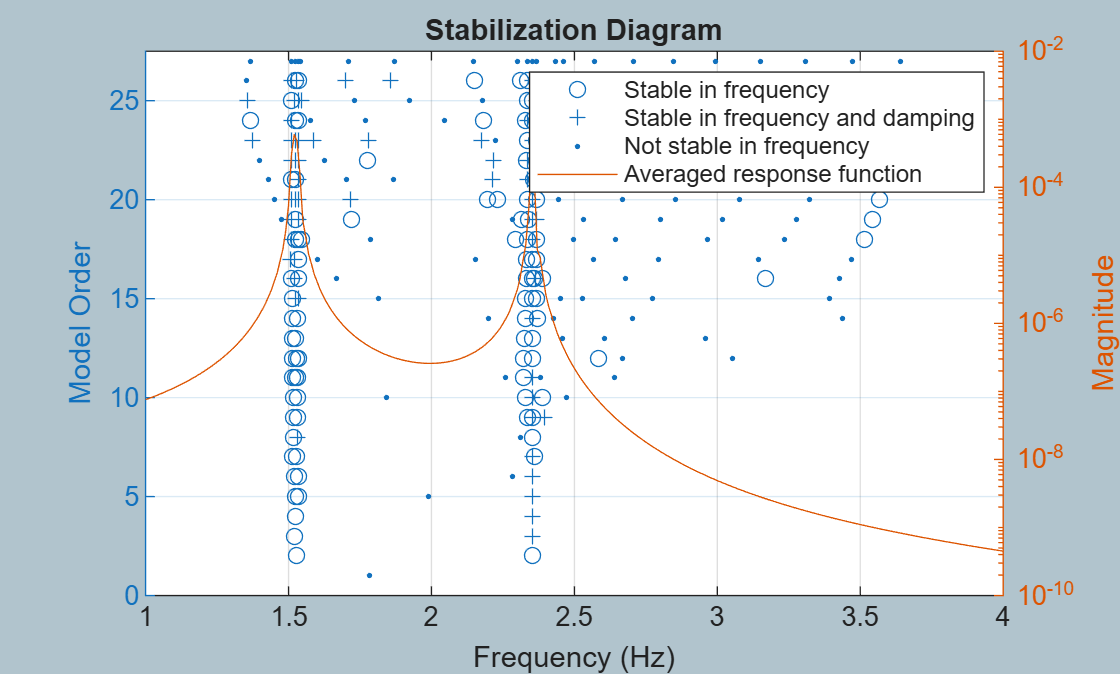

fn_sd =        NaN         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.5265    2.3526         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.5226    2.3520       NaN         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.5228    2.3520       NaN       NaN         0         0         0         0         0         0         0         0         0         0         0         0         0         

MAXMODES = 50;

figure   % for the STABILIZATION plot
    fn_sd = modalsd( all_frf, all_f, my_config_S.Fs_Hz, ...
                     MaxModes=MAXMODES, ...
                     FreqRange=roi.range_Hz, ...
                     FitMethod=try_it_FitMethod)

remove NaNs and ZEROS

FN_HZ_ALL =   rmmissing(fn_sd(:));
tmp_ind   =  FN_HZ_ALL == 0;
FN_HZ_ALL(tmp_ind) = [];

## Explore the distribution of the identified modes

REMEMBER: many of the modes will NOT be real modes, rather they will be computational ones that we need to ignore.

- 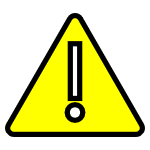 **NOTE:** our bin width may need some "trial/error" tuning.

DF_bin               = 0.1; %1; %1; %1; %0.2; %0.25; % (Hz)

Define the bin edges for our histogram:

f_edges              = [roi.range_Hz(1):DF_bin:roi.range_Hz(2)];

And plot a histogram of the natural frequencies:

figure;
  histogram(FN_HZ_ALL,  f_edges);
    xlabel('freq wn [hz]');  ylabel('counts');
    axis tight, grid on
    title("Histogram of counts for"+newline+"NATURAL frequency \omega_n")

## Select modes based on a count threshold

As a first step in trying to distinguish between true modes and "ghost" modes, let's consider modes that occurred a lot

-  **NOTE:**  the MIN count threshold may need some "trial/error" tuning.

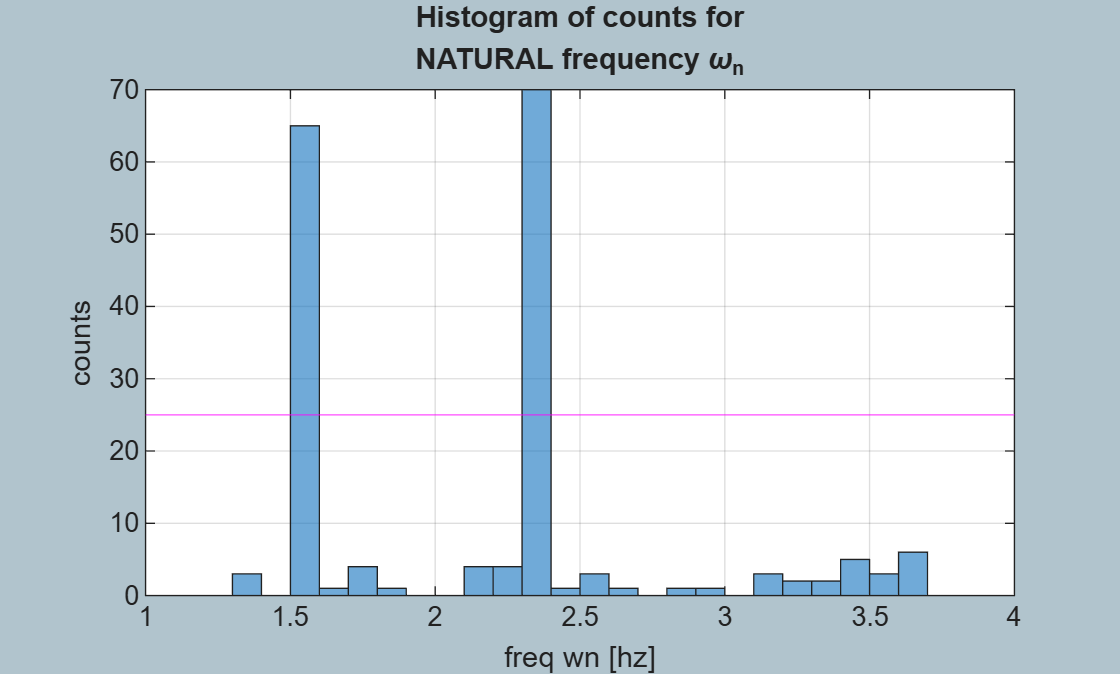

MIN_REQUIRED_COUNTS   = 0.5*MAXMODES;

% show this threshold on the histogram
hold on
  yline(MIN_REQUIRED_COUNTS, "-m")

So find the most "full" bins

[N_counts,~,bin_ind]  = histcounts(FN_HZ_ALL,  f_edges);
candidate_bin_ID_list = find(N_counts >= MIN_REQUIRED_COUNTS);

Process and display these full bins:

my_fhz_list_FROM_HIST  = [];
for kk=1:length(candidate_bin_ID_list)
     the_bin_ID       = candidate_bin_ID_list(kk); 
     tf_list          = (bin_ind == the_bin_ID);    
     my_fhz_list_FROM_HIST(kk)  = mean(FN_HZ_ALL(tf_list));
end
[~,sI]                 = sort(my_fhz_list_FROM_HIST);
my_fhz_list_FROM_HIST  = my_fhz_list_FROM_HIST(sI)

my_fhz_list_FROM_HIST =     1.5250    2.3501


So from the stabilization diagram, how many modes do you think we should try and fit ?

NUM_MODES_TO_FIT = 6    

NUM_MODES_TO_FIT = 6

### Now do a MODAL fit:

- see DOC for  [`modalfit()`](matlab:  doc  modalfit) 

 **NOTE:**  

- We'll specify the frequencies extracted from our histogram and pass these into  [`modalfit()`](matlab:  doc  modalfit) as 'PhysFreq'.  

- ***Overspecifying the number of modes gives better*** (?) results.

[fn,dr,ms,ofrf] = modalfit( all_frf, all_f, my_config_S.Fs_Hz, ...
                            NUM_MODES_TO_FIT, ...
                            PhysFreq=my_fhz_list_FROM_HIST, ...
                            FreqRange=roi.range_Hz, ...
                            FitMethod=try_it_FitMethod);

Remove any Nans:

tmp_ind  = ~isnan(fn) & ~isnan(dr);
fn_clean = fn(tmp_ind);
dr_clean = dr(tmp_ind);
ms_clean = ms(tmp_ind);

if(length(fn_clean) ~= length(fn))
    fprintf("\n .... Have deleted <%d> NAN or INF mode values", length(fn)-length(fn_clean));
end

Tabulate these

array2table([fn_clean(:), dr_clean(:)],'VariableNames',{'fn_hz','zeta'})

ans = 2×2 table
    fn_hz       zeta   
    ______    _________

    1.5202    0.0033575
     2.352    0.0018741

	Get insights using Copilot


## Let's focus on $H_{11}$

Do a BETTER fit by computing residues of 1st order sections

[my_R, my_e, my_f] = bh_Modal.bh_calc_resids_LIVE( fn_clean,  ...
                                                   dr_clean, ...
                                                   roi.f_hz_col, ...
                                                   roi.frf)

my_R = 1.0e-03 *

  -0.0078 - 0.3123i
   0.0009 - 0.0401i


my_e = -1.8302e-05 - 2.1189e-06i

my_f = -0.0023 - 0.0006i

## Prune  based on PHASE of RESIDUES:

A ***NORMAL*** pole/mode is characterized by a RESIDUE phase of +/- 90 degrees, so only keep candidates that have a RESIDUE phase angle near this.  For rationale see  the file [`APPENDIX_01_Modal_Model_Representation.mlx`](matlab:  edit  bh_Modal.APPENDIX_01_Modal_Model_Representation) 

phase_rad_list =   angle(my_R);
phase_rad_list =   abs(phase_rad_list);  % ABSOLUTE value of R's phase angle
phase_deg_list =   phase_rad_list * 180/pi;

% look for candidates "close" to 90 degrees
% inds_to_keep = find( phase_deg_list<(115) & phase_deg_list>(70) );
inds_to_keep = find( phase_deg_list<(120) & phase_deg_list>(70) );
assert(~isempty(inds_to_keep),'ERROR: you have trashed ALL of them ');

% So keep these
my_fhz_list         = fn_clean(inds_to_keep);
my_damp_list        = dr_clean(inds_to_keep);
my_R                = my_R(inds_to_keep); 

Visually confirm Residues have phases close to 90 degrees OR -90 degrees

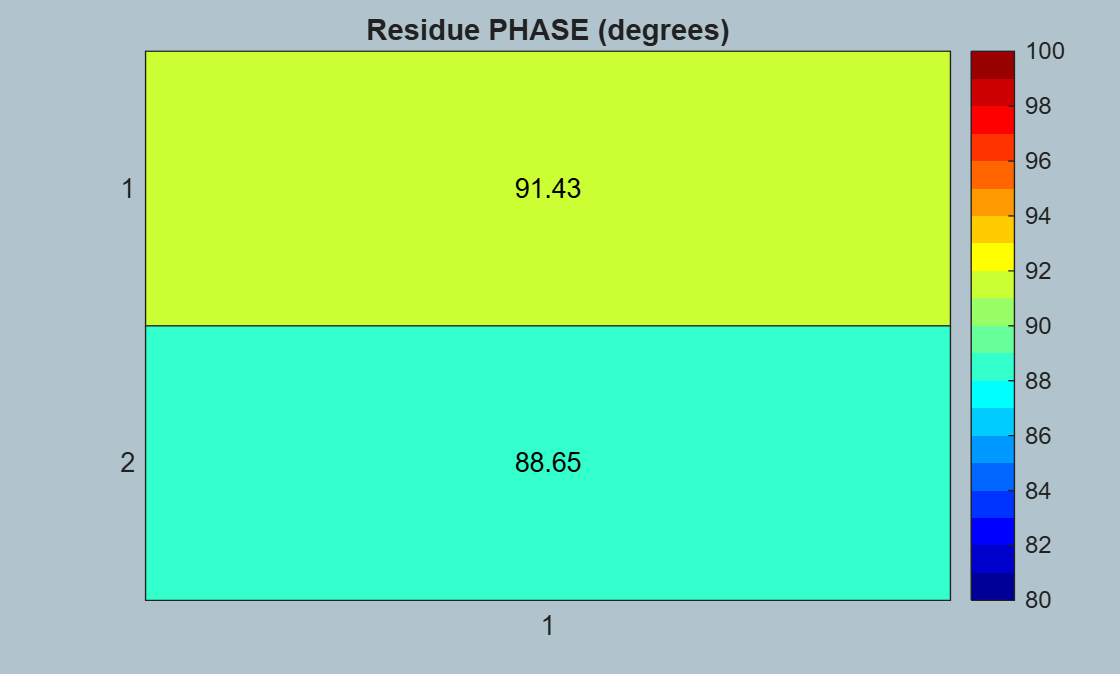

tmp_res_phas_degs = abs( rad2deg(angle(my_R)) );

figure;
    heatmap(tmp_res_phas_degs, "Colormap", jet(20) );
        title("Residue PHASE (degrees)")
         clim([80 100])

## Summarize the Identified MODAL properties

fprintf("\n FINAL results ----> ")


 FINAL results ----> 

RESULTS_tab = array2table([my_fhz_list(:), my_damp_list(:), (2*pi*my_fhz_list(:))],...
                            'VariableNames',{'fn_Hz','zeta', 'wn_radpersec'});
RESULTS_tab

RESULTS_tab = 2×3 table
    fn_Hz       zeta       wn_radpersec
    ______    _________    ____________

    1.5202    0.0033575       9.5517   
     2.352    0.0018741       14.778   

	Get insights using Copilot


## So what does the curve fit look like ?

We've completed the curve fit.  So let's combine our identified terms into a final model:

- 
$$\mathrm{FRF}=\;\left(\sum_{k=1}^N \left.\;\;\frac{R_k }{s-\lambda_k }+\;\frac{\bar{R_k } }{s-\bar{\lambda_k } }\right)\;\;\;+\;\;\;\;\;\frac{f}{s^2 }\;\;\;+\;\;\;\;\;\;e\right.$$


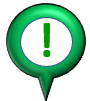We'll use a custom **Value Class** defined in the file  [`CLS_sdyn_frf.m`](matlab:  edit  bh_Modal.CLS_sdyn_frf) to represent the FRF

- `CLS_sdyn_frf(the_damping_zeta, ``the_wn_rads``, the_R, the_E, the_F)`

my_sdyn_OBJ = bh_Modal.CLS_sdyn_frf( RESULTS_tab.zeta,         ...
                                     RESULTS_tab.wn_radpersec, ...
                                     my_R, my_e, my_f);

my_sdyn_OBJ.s_w_fhz_col = roi.f_hz_col;

Echo a summary of our model:

my_sdyn_OBJ.print()


---------------------------------------------------------------------------
 ID_label = sdt_foo

 mode#      Wn[Hz]       DAMP[-]       Real(R)          Imag(R)        Phase(R)[degs]      
  1          1.520      0.00336      -7.78128e-06     -0.000312306     -91.43  
  2          2.352      0.00187       9.47772e-07      -4.0123e-05     -88.65  

 E = -1.83016e-05 + i*-2.11886e-06
 F = -0.00230245 + i*-0.000613063

#### Plotting:  Part 1 - Plot the model against the Measurement data

figure;
  hax(1) = subplot(2,1,1); 
       plot(roi.f_hz_col, 20*log10(abs(roi.frf)), "-r", "DisplayName","MEAS")
           grid on; axis tight
           xlabel("(Hz)");   ylabel("(dB)");
           
  hax(2) = subplot(2,1,2); 
       plot(roi.f_hz_col, rad2deg(angle(roi.frf)), "-r")
           grid on; axis tight
           xlabel("(Hz)");  ylabel("(degrees)")

hold(hax(1),"on")
    axes(hax(1))
    plot(my_sdyn_OBJ.s_w_fhz_col, my_sdyn_OBJ.db, "-b","DisplayName","fit");

hold(hax(2))

Current plot held


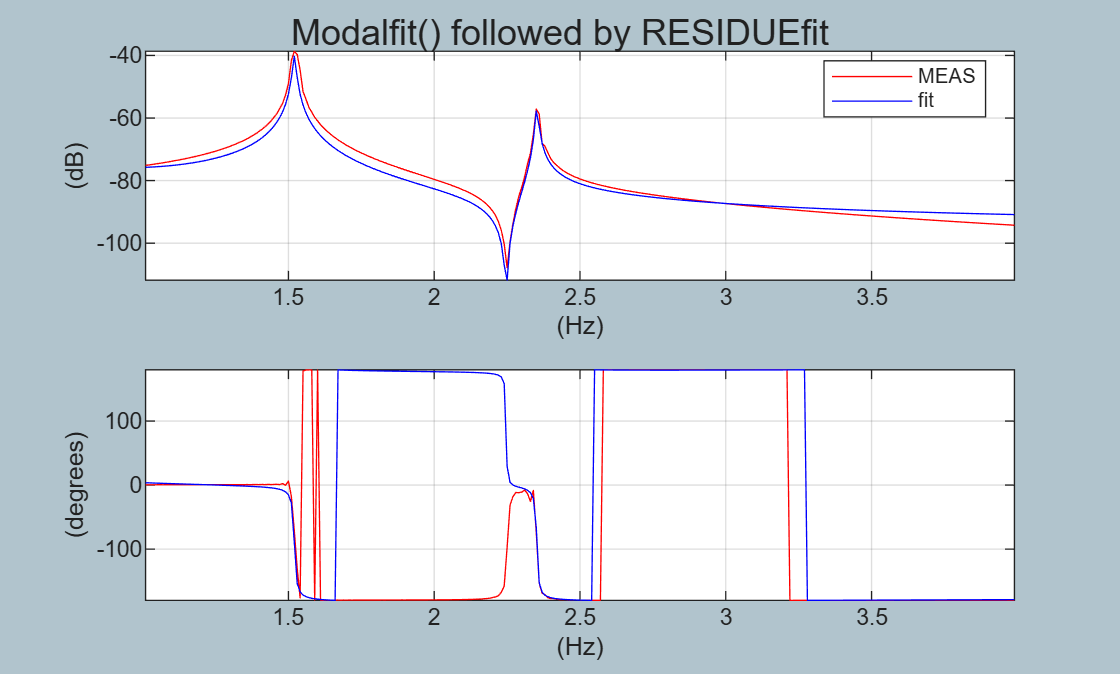

    axes(hax(2))
    plot(my_sdyn_OBJ.s_w_fhz_col, my_sdyn_OBJ.phase("DEGS"), "-b");

legend(hax(1), "Location", "best")

linkaxes(hax, "x")
sgtitle("Modalfit() followed by RESIDUEfit")

#### Plotting:  Part 2 - Plot the model in 3D

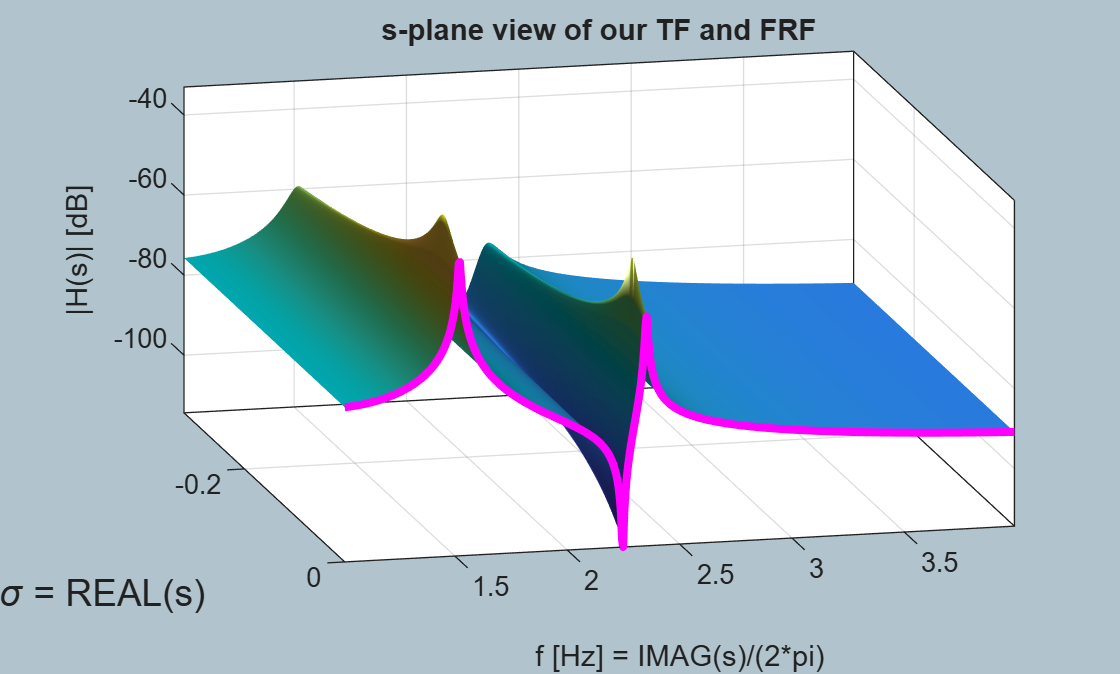

my_sdyn_OBJ.plot_3d_db()

## Extract MODE shapes

For each FRF

- 
$$\mathrm{FRF}=\;\left(\sum_{k=1}^N \left.\;\;\frac{R_k }{s-\lambda_k }+\;\frac{\bar{R_k } }{s-\bar{\lambda_k } }\right)\;\;\;+\;\;\;\;\;\frac{f}{s^2 }\;\;\;+\;\;\;\;\;\;e\right.$$


Compute the residues for every each mode in each FRF

- `size(my_R_mat) == NUM_MODES x NUM_CHANNELS`

my_R_mat = NaN( length(RESULTS_tab.fn_Hz),  size(all_frf, 2) );

for kk=1:size(my_R_mat,2)
 
    [my_R, my_e, my_f]  = bh_Modal.bh_calc_resids_LIVE( RESULTS_tab.fn_Hz, ...
                                                        RESULTS_tab.zeta, ...
                                                        roi.f_hz_col, ...
                                                        roi.frf_all(:,kk)    );
    my_R_mat(:,kk) = my_R(:);
end

Visually confirm Residues have phases close to 90 degrees OR -90 degrees

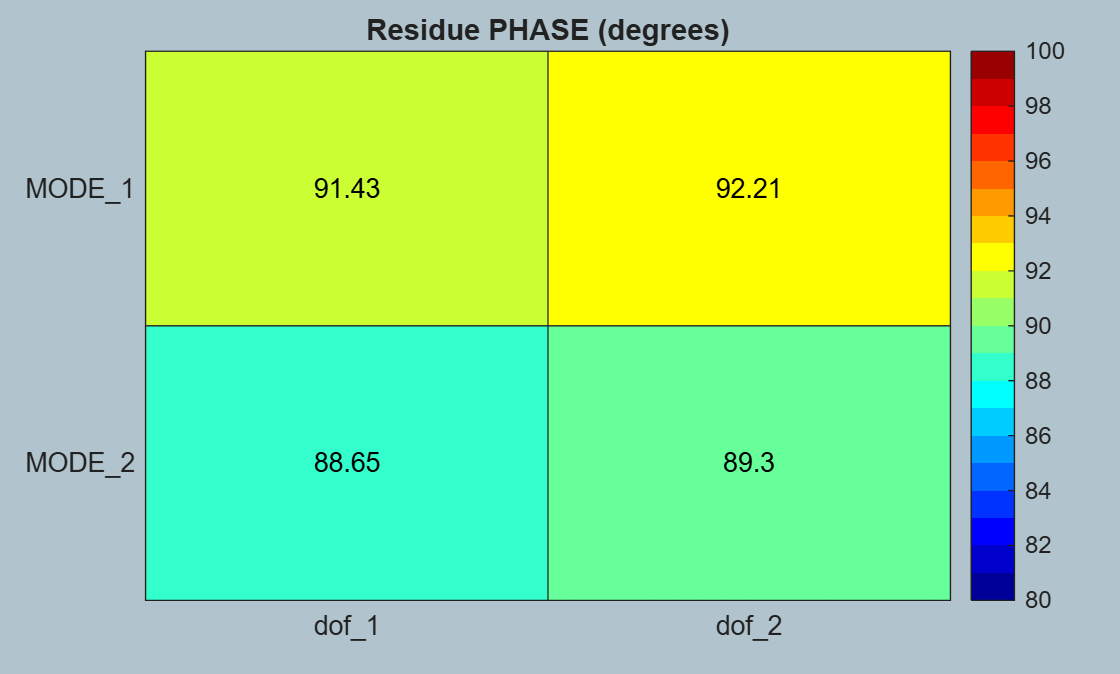

tmp_res_phas_degs = abs( rad2deg(angle(my_R_mat)) );

figure;
     heatmap( tmp_res_phas_degs, "Colormap", jet(20), ...
              YDisplayLabels="MODE_"+(1:height(my_R_mat)), ...
              XDisplayLabels="dof_"+(1:2), ...
              Interpreter="none" );
        title("Residue PHASE (degrees)")
        clim([80 100])

#### Extract Mode shapes 

Recall the format of our RESIDUE matrix

- `size(my_R_mat) == NUM_MODES x NUM_CHANNELS`

Assume Proportional damping and convert the Residues into normal mode data

md_shapes = imag(my_R_mat);

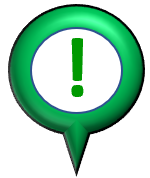Reshape so that the COLUMNS represent the mode shapes .. and normalise based on the 1st element of each column

md_shapes = md_shapes.';
md_shapes = md_shapes ./ md_shapes(1,:)

md_shapes =     1.0000    1.0000
    1.6931  -12.2527


#### Compare against the Analytic solution:

eVec_PHI ./ eVec_PHI(1,:)

ans =     1.0000    1.0000
    1.8443  -10.8443


# Using the System Identification toolbox

Extracting MODAL properties from measured FRFs is an example of a more general problem referred to as "**System Identification**" (aka SYS ID).  MATLAB has a dedicated library of algorithms for doing SYS ID - the [**System Identification toolbox**](https://www.mathworks.com/help/releases/R2025b/ident/index.html).  So ? - So let's use a couple of the functions from the  System Identification toolbox to create a model and then extract our modal properties.

## Do another fit  - using the `ssest()` function

Review the following DOC pages:

- [`frd()`](matlab: doc frd) , [`ssest()`](matlab: doc ssest)`, `[`tf_est()`](matlab: doc tfest)

First put our measured FRF data into a data container that the SYS ID toolbox needs:

sys_frd = frd(roi.frf, roi.f_hz_col, "FrequencyUnit","Hz");

Now invoke two of the model estimation algorithms fro the SYS ID toolbox:

ss_ORDER = 4;  % say 2 x the number of modes

ss_sys = ssest(sys_frd, ss_ORDER);
tf_sys = tfest(sys_frd, ss_ORDER);

Extract our modal properties

[wn_est, zeta_est] = damp(ss_sys);
f_est              = wn_est/(2*pi)

f_est =     1.5230
    1.5230
    2.3522
    2.3522


Plot the identified models

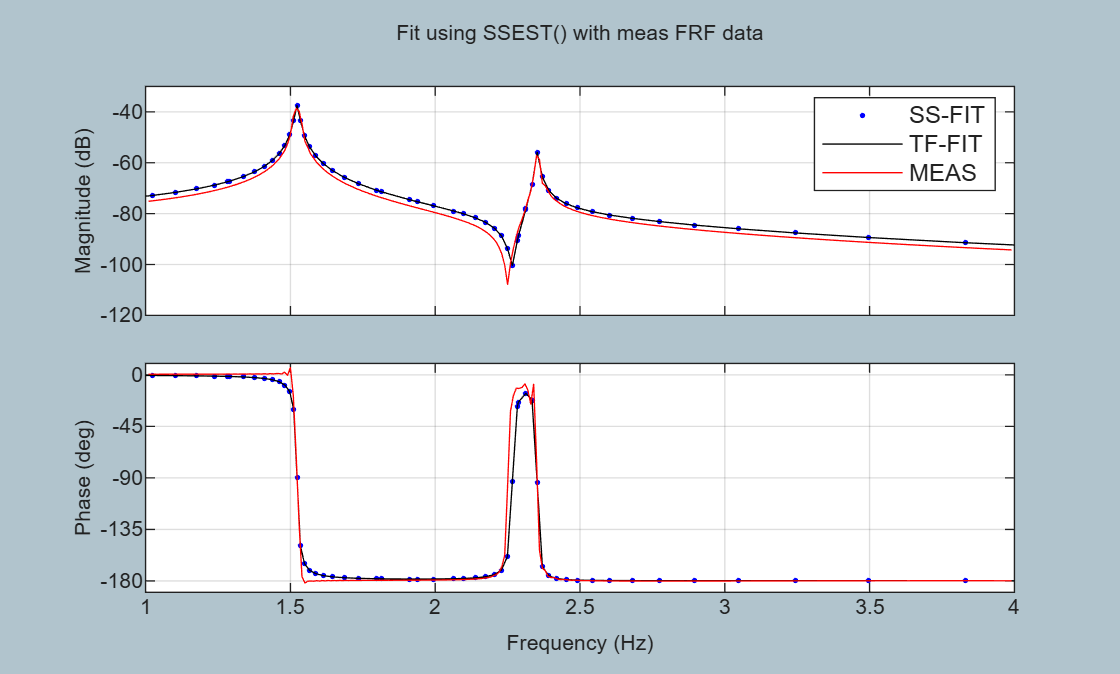

my_opts = bodeoptions;
my_opts.FreqUnits = "Hz";
my_opts.XLim  = {[1,4]};
my_opts.FreqScale = "Linear";
%my_opts.PhaseVisible = "off";
figure;
    bodeplot(ss_sys,"b.", tf_sys,"-k", sys_frd, "-r",my_opts);
        grid on
        title("Fit using SSEST() with meas FRF data")
        legend(["SS-FIT","TF-FIT", "MEAS"],"Location", "best")

        %axis("tight")